clear all;

% Read in csv
energy_data = readtable("NI_hourly.csv");

% General disp
disp(energy_data);

         Datetime          NI_MW
    ___________________    _____

    2004-12-31 01:00:00     9810
    2004-12-31 02:00:00     9001
    2004-12-31 03:00:00     8509
    2004-12-31 04:00:00     8278
    2004-12-31 05:00:00     8089
    2004-12-31 06:00:00     8208
    2004-12-31 07:00:00     8431
    2004-12-31 08:00:00     8891
    2004-12-31 09:00:00     9098
    2004-12-31 10:00:00     9237
    2004-12-31 11:00:00     9508
    2004-12-31 12:00:00     9583
    2004-12-31 13:00:00     9679
    2004-12-31 14:00:00     9614
    2004-12-31 15:00:00     9475
    2004-12-31 16:00:00     9427
    2004-12-31 17:00:00     9431
    2004-12-31 18:00:00    10319
    2004-12-31 19:00:00    11518
    2004-12-31 20:00:00    11409
    2004-12-31 21:00:00    11172
    2004-12-31 22:00:00    10877
    2004-12-31 23:00:00    10506
    2005-01-01 00:00:00    10115
    2004-12-30 01:00:00    10385
    2004-12-30 02:00:00     9697
    200

% Check min and max values
disp(min(energy_data.Datetime));

   2004-05-01 01:00:00



disp(max(energy_data.Datetime));

   2011-01-01 00:00:00



% Extract hour value to separate column, and remove value from dt-column
energy_data.hour = hour(energy_data.Datetime);
energy_data.date = dateshift(energy_data.Datetime, 'start', 'day'); 

energy_data = sortrows(energy_data,["Datetime"]);

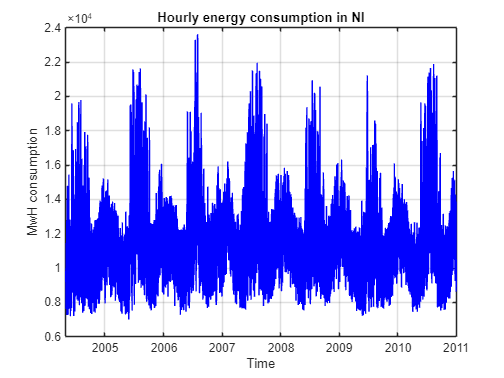

% Plot out with dt
% Visualizes certain patterns over time, but not in a consistent manner
figure;
plot(energy_data.Datetime, energy_data.NI_MW,'Color','blue');
xlabel('Time');
ylabel('MwH consumption');
title('Hourly energy consumption in NI');
grid on;

% Format date 
energy_data.date.Format = 'yyyy-MM-dd';

% Drop DT-column after
energy_data.Datetime = [];

% Check quick visual
disp(energy_data);

    NI_MW    hour       date   
    _____    ____    __________

     9198      1     2004-05-01
     8570      2     2004-05-01
     8183      3     2004-05-01
     7917      4     2004-05-01
     7828      5     2004-05-01
     7806      6     2004-05-01
     8082      7     2004-05-01
     8267      8     2004-05-01
     8830      9     2004-05-01
     9381     10     2004-05-01
     9712     11     2004-05-01
     9890     12     2004-05-01
     9833     13     2004-05-01
     9714     14     2004-05-01
     9540     15     2004-05-01
     9465     16     2004-05-01
     9329     17     2004-05-01
     9349     18     2004-05-01
     9269     19     2004-05-01
     9384     20     2004-05-01
     9677     21     2004-05-01
     9988     22     2004-05-01
     9873     23     2004-05-01
     9318      0     2004-05-02
     8697      1     2004-05-02
     8226      2     2004-05-02
 

% Pivot to hourly data for svd
pivoted_energy_data = unstack(energy_data,'NI_MW', 'hour', 'AggregationFunction', @mean, 'VariableNamingRule','preserve');

pivoted_energy_data = sortrows(pivoted_energy_data,["date"]);
disp(pivoted_energy_data);

       date         0        1        2        3        4        5        6        7        8        9       10       11       12       13       14       15       16       17       18       19       20       21       22       23  
    __________    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____ 

for i = 1:width(pivoted_energy_data)-1
     column_data = pivoted_energy_data{:, i+1};  % i+1 because we want to skip the first column
    
    % Calculate the column mean (ignoring NaN values)
    column_mean = nanmean(column_data);
    
    % Replace NaN values with the column mean
    column_data(isnan(column_data)) = column_mean;
    
    % Update the column in the table
    pivoted_energy_data{:, i+1} = column_data;
end


% Pivot to matrix for svd w/out date column
matrix = table2array(pivoted_energy_data(:,2:end));


% Check for nan values
if any(isnan(matrix(:)))
    disp('Matrix contains NaN values!');
end
disp(sum(isnan(matrix(:))));

     0



% Run SVD
[U, S, V] = svd(matrix, 'econ');

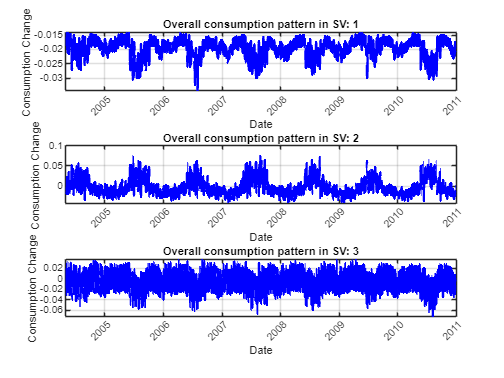

% Overall consumption patterns in first 5 left vectors
% Certain seasonal patterns in consumption can be detected
figure;
for i = 1:3
    subplot(3,1,i);
    plot(pivoted_energy_data.date, U(:, i), 'LineWidth', 2, 'Color','blue');
    title(['Overall consumption pattern in SV: ' num2str(i)]);
    xlabel('Date');
    ylabel('Consumption Change');
    xtickangle(45);
    grid on;
end

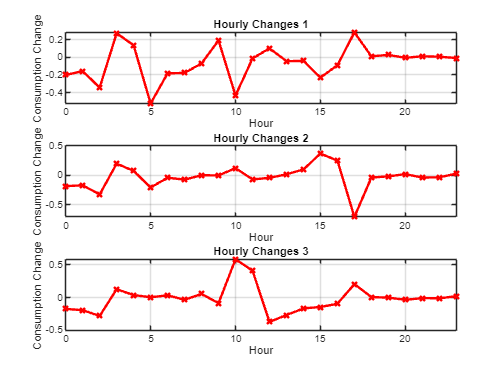

% Three most dominant patterns in features (Hours)
% Certain hourly consumption patterns can be detected
% Consumption increases pre-and post working hours
figure;
for i = 1:3
    subplot(3,1,i);
    plot(0:23, V(i, :),'x-', 'LineWidth', 2, 'Color','red');
    title(['Hourly Changes ' num2str(i)]);
    xlabel('Hour');
    ylabel('Consumption Change');
    xlim([0 23]);  
    grid on;
end

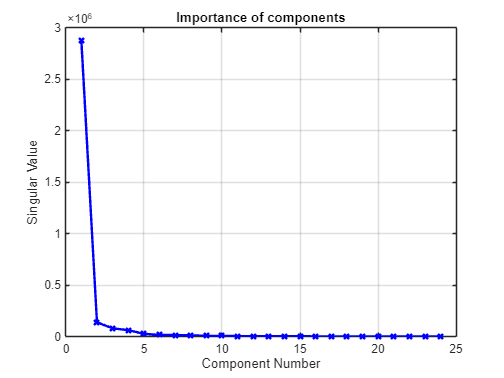

% SV importance. Most variance captured by first few components
sing_vals = diag(S);
figure;
plot(sing_vals, 'x-','LineStyle','-','LineWidth',2,'Color','blue');
xlabel('Component Number');
ylabel('Singular Value');
title('Importance of components');
grid on;